# Script 8: Model Development

There are many different approaches and techniques for modeling systems. This script introduces some of the ways to use machine learning to forecast the electricity demand 24 hours in advance.

Reproducible results

rng default

## Load in merged data set

load('nyiso_merged.mat')
nyiso = timetable2table(nyiso);

## How should we model New York?

The first question we need to answer is how to model the state of New York. Should we create one model that understands the entire state, or model each region separately?

The answer depends on how similarly the different regions behave. If they all exhibit very similar behavior, then we may be able to use only one model. However as the box plot below shows, the magnitudes and ranges exhibited by the demand varies greatly by region. This should not come as a surprise, as rural upstate New York has little in common with downtown New York City. Because of this difference in behavior, we will model each zone separately.

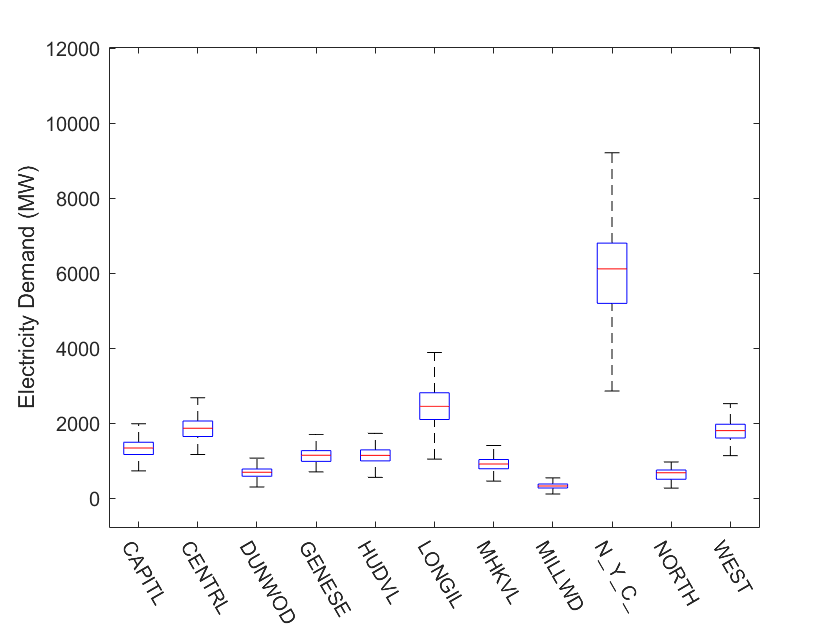

% restack energy data to make it easier to do a box plot
nyisoStack = stack(nyiso(:,2:12),1:11,'NewDataVariableName','Load',...
    'IndexVariableName','Name');
figure
boxplot(nyisoStack.Load,nyisoStack.Name,'Symbol','w')
xtickangle(-60);
ylabel('Electricity Demand (MW)')

## Start with modeling a single zone

We'll start by evaluating our models on one of the zones, in this case the New York City zone. The weather station at Laguardia airport covers most of the zone. Once we understand how to model a single zone, we can expand our analysis to other zones.

% Pull out relevant data into separate table to make it easier to work with
modelData = nyiso(:, {'Date', 'N_Y_C_', 'KLGA'});
% Change the table column names to be more general
modelData.Properties.VariableNames(2:3) = {'Load', 'Temperature'};

## Create temporal predictors

In order to build an accurate model, we need useful predictors to work with. A common technique with temporal predictors is to break them into their separate parts so they can be varied independently of each other.

% Create temporal predictors
modelData.Hour = modelData.Date.Hour;
modelData.Month = modelData.Date.Month;
modelData.Year = modelData.Date.Year;
modelData.DayOfWeek = weekday(modelData.Date);
modelData.isWeekend = isweekend(modelData.Date);

% Pull the temperature and dew point apart into separate columns as
% expected by the machine learning techniques
modelData.Temp = modelData.Temperature(:, 1);
modelData.DewPnt = modelData.Temperature(:, 2);
modelData.Temperature = [];

## Hour, Month and DayOfWeek are Cyclical

We have now broken our time stamp into its components. However we are not representing them in the most accurate way possible. We are using a 24 hour day, but for simplicity consider the 12 hour clock in the figure below.

## 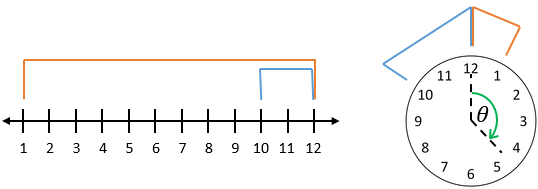

Machine learning algorithms have no understanding of time. They only know of numbers on the number line. So if they see Hour values 1, 10 and 12, they will incorrectly assume that 12 is much closer to 10 than to 1. However we know that the Hour variable is cyclical and that 12 is actually closer 1 than it is to 10. To represent this more accurately, we can transform the hour variable into two variables using `sin` and `cos.` This will allow us to accurately capture the cyclical nature of the data in a way that the machine learning algorithms can understand. The Month and DayOfWeek variables also exhibit similar cyclical behavior.

Note that in our data we use a 24 hour clock instead of the 12 hour clock shown in the figure above, and treat the angle as clockwise from the vertical.

modelData.HourX = sin(2*pi*modelData.Hour/24);
modelData.HourY = cos(2*pi*modelData.Hour/24);
modelData.Hour = [];
modelData.MonthX = sin(2*pi*modelData.Month/12);
modelData.MonthY = cos(2*pi*modelData.Month/12);
modelData.Month = [];
modelData.DayOfWeekX = sin(2*pi*modelData.DayOfWeek/7);
modelData.DayOfWeekY = cos(2*pi*modelData.DayOfWeek/7);
modelData.DayOfWeek = [];

## Lagged predictors

The load data itself can be used as a predictor. We could use a traditional time series analysis, but a look at the autocorrelation will show an interesting pattern. The peaks in the autocorrelation at the 24 and 168 hour lags suggest use of lagged predictors of 1 and 7 days.

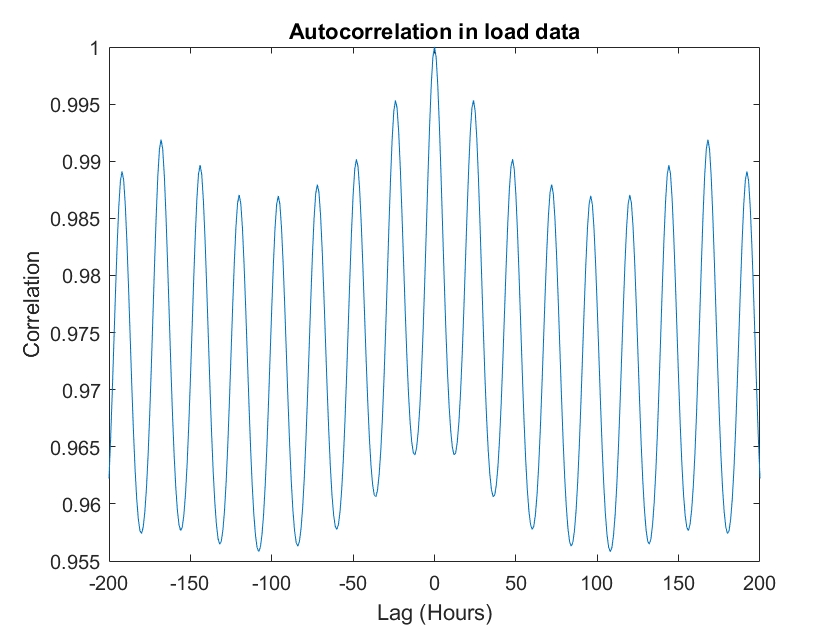

c = xcorr(modelData.Load, 200, 'coeff');
figure
plot(-200:200, c)
title('Autocorrelation in load data')
xlabel('Lag (Hours)')
ylabel('Correlation')

Create the prior day and week (24, 168 hour) lag variable since we have regularized the data using timetables, we can simply look back by 24 rows to get the value from 24 hours ago

modelData.PriorDay = nan(height(modelData), 1);
modelData.PriorDay(25:end) = modelData.Load(1:end-24);
modelData.PriorWeek = nan(height(modelData), 1);
modelData.PriorWeek(169:end) = modelData.Load(1:end-168);

## Split to training and testing

Here we split the data into training and testing sets based on the date. More sophisticated techniques such as cross validation are also available. We will pull out the year 2012 for testing and train on the rest of the data.

idxtrain = modelData.Date < datetime('1-Jan-2012','TimeZone','America/New_York') | ...
    modelData.Date > datetime('31-Dec-2012','TimeZone','America/New_York');
idxtest = ~idxtrain;
% split the table into training and testing sets
modeltrain = modelData(idxtrain, 2:end);
modeltest = modelData(idxtest, 2:end);
% some of the machine learning functions expect separate matricies for the
% inputs and output
Xtrain = modeltrain{:,2:end};
Ytrain = modeltrain{:,1};
Xtest = modeltest{:,2:end};
Ytest = modeltest{:,1};

## Train different models using Regression Learner App

One of the most challenging parts of a machine learning workflow is that there is no way to know with certainty what modeling technique will work best on a particular dataset until you just try them out and see what happens. The Statstics and Machine Learning Toolbox has a pair of machine learning apps to make this iterative process much easier. In this case we will use the Regression Learner App to try out different regression techniques. After opening the app, start a new session with the `modeltrain` variable and be sure to pick the Load column as the Response. After importing the data you can try out many different techniques. After training the models, you can generate the code needed to retrain the same model on new data. In the following sections we use that code to examine several techniques.

## Regression

Fit and examine a simple linear model. This model has a small number of parameters, only some of which are significant according to their pValue. 

mdl_lm = fitlm(modeltrain, 'ResponseVar', 'Load')

mdl_lm = Linear regression model:
    Load ~ 1 + Year + isWeekend + Temp + DewPnt + HourX + HourY + MonthX + MonthY + DayOfWeekX + DayOfWeekY + PriorDay + PriorWeek

Estimated Coefficients:
                   Estimate       SE         tStat       pValue   
                   ________    _________    _______    ___________

    (Intercept)     2941.5        1207.7     2.4357       0.014864
    Year           -1.3796       0.59984       -2.3       0.021453
    isWeekend_1    -653.39        6.3052    -103.63              0
    Temp            10.038       0.27907     35.969    1.0599e-280
    DewPnt          1.0971       0.20807     5.2728     1.3475e-07
    HourX          -65.732        3.1773    -20.688      8.673e-95
    HourY         

## Regression Performance

Evaluate the performance of the regression model using the mean absolute percent error metric, which is commonly used in electricity demand forecasting applications. 

Ytrain_lm = predict(mdl_lm, modeltrain);
fprintf('Linear Model Training set MAPE: %0.2f%%\n', ...
    mape(Ytrain, Ytrain_lm)*100);

Linear Model Training set MAPE: 5.05%


## Stepwise Linear Regression

According to the simple linear model some of the inputs may not be helpful. To automate the process of find the right combination, we can use a stepwise linear model. The stepwise model will add and remove inputs in different combinations until it finds a combination where everything that is included is significant, and everything that has not been added would not be significant.

The stepwise model can also automatically add both quadratic and interaction terms to the model. Including interaction terms adds `nchoosek(12,2)=66` additional inputs for consideration, so for the sake of time we ignore interactions here.

We can see that the stepwise linear model keeps all of our original inputs, and also adds some quadratics, though not all possible quadratics. Its error on the training data is one percentage point better than the simple linear model.

mdl_steplm = stepwiselm(modeltrain,'constant','ResponseVar','Load','Upper','purequadratic')

1. Adding isWeekend, FStat = 4912.2354, pValue = 0
2. Adding Temp, FStat = 24012.8447, pValue = 0
3. Adding DewPnt, FStat = 2992.4347, pValue = 0
4. Adding HourX, FStat = 31610.9307, pValue = 0
5. Adding HourY, FStat = 10962.6792, pValue = 0
6. Adding PriorDay, FStat = 4605.5062, pValue = 0
7. Adding DayOfWeekX, FStat = 12375.144, pValue = 0
8. Adding PriorWeek, FStat = 54.8637, pValue = 0
9. Adding Temp^2, FStat = 33269.9726, pValue = 0
10. Adding DewPnt^2, FStat = 1608.6807, pValue = 0
11. Adding PriorWeek^2, FStat = 1678.0068, pValue = 0
12. Adding DayOfWeekX^2, FStat = 1358.9352, pValue = 1.3768337e-294
13. Adding MonthX, FStat = 706.541, pValue = 6.939685e-155
14. Adding MonthY, FStat = 2673.7377, pValue = 0
15. Adding Year, FStat = 621.5283, pValue = 1.418671e-136
16. Adding MonthX^2, FStat = 395.6994, pValue = 8.42567e-88
17. Adding HourX^2, FStat = 198.971, pValue = 4.051791e-45
18. Adding PriorDay^2, FStat = 23.9293, pValue = 1.00167e-06


mdl_steplm = Linear regression model:
    Load ~ 1 + Year + isWeekend + Temp + DewPnt + HourX + HourY + MonthX + MonthY + DayOfWeekX + PriorDay + PriorWeek + Temp^2 + DewPnt^2 + HourX^2 + MonthX^2 + DayOfWeekX^2 + PriorDay^2 + PriorWeek^2

Estimated Coefficients:
                     Estimate          SE         tStat       pValue   
                    ___________    __________    _______    ___________

    (Intercept)           25853        950.87     27.189    6.4003e-162
    Year                -11.607       0.47047     -24.67     8.598e-134
    isWeekend_1         -494.95        3.4934    -141.68              0
    Temp                -70.742       0.73217     -96.62              0
    DewPnt              -10.063       0.44608     -22.56    2.7849e-112
    

Ytrain_steplm = predict(mdl_steplm,modeltrain);
fprintf('Linear Model Training set MAPE: %0.2f%%\n', ...
    mape(Ytrain, Ytrain_steplm)*100);

Linear Model Training set MAPE: 4.06%


## Parallel Computing Environment

Many MATLAB algorithms can take advantage of parallel processing to speed up calculations. Here we open a pool of workers to harness the full computational capabilities of the CPU running this script

if isempty(gcp('nocreate'))
    parpool('local')
end

## Ensemble Regression Tree

Train a bagged regression tree model on the same data set. Bagging involves building an ensemble of trees, each trained on a resampled subset of the training set. During prediction, each tree creates a forecast and the average of all forecasts is taken. This can produce a strong model. In this case, it produces the best model for the training data.

opts = statset('UseParallel', 'always');
mdl_tb = TreeBagger(30, Xtrain, Ytrain, 'method', 'regression', ...
                 'options', opts, 'NVarToSample','all');
Ytrain_tb = predict(mdl_tb, Xtrain);

fprintf('Treebagger Training set MAPE: %0.2f%%\n', ...
    mape(Ytrain, Ytrain_tb)*100);

Treebagger Training set MAPE: 1.25%


## Neural networks

Fit a feed-forward Neural Network to solve the regression problem. The network can be estimated and evaluated using the interactive Neural Fitting Tool (nftool) app. The app automatically generates code, some of which has been included below to do the same work programmatically. We can see that the neural network is a significant improvement on the training data over the two linear models.

trainFcn = 'trainlm';  % Levenberg-Marquardt training algorithm

% Create a Fitting Network
hiddenLayerSize = 20; 
net = fitnet(hiddenLayerSize,trainFcn);
net.trainParam.epochs = 100;
net.trainParam.showWindow = 0;

% Train the Network
mdl_net = train(net,Xtrain',Ytrain','UseParallel','yes');
Ytrain_nn = mdl_net(Xtrain')';

% Error metric for the neural network.
fprintf('Neural Net Training set MAPE: %0.2f%%\n', ...
    mape(Ytrain, Ytrain_nn)*100);

Neural Net Training set MAPE: 1.96%


## Compare Models on Test Set

Model performance so far has been reported only on the training set. A true measure of the generalization capability of the model is measured by its performance on a holdout dataset. For example, even though the bagged regression tree has a lower MAPE on the training set than the neural net, it has a higher MAPE on the test set indicating that it is likely to have overfit to the training set. 

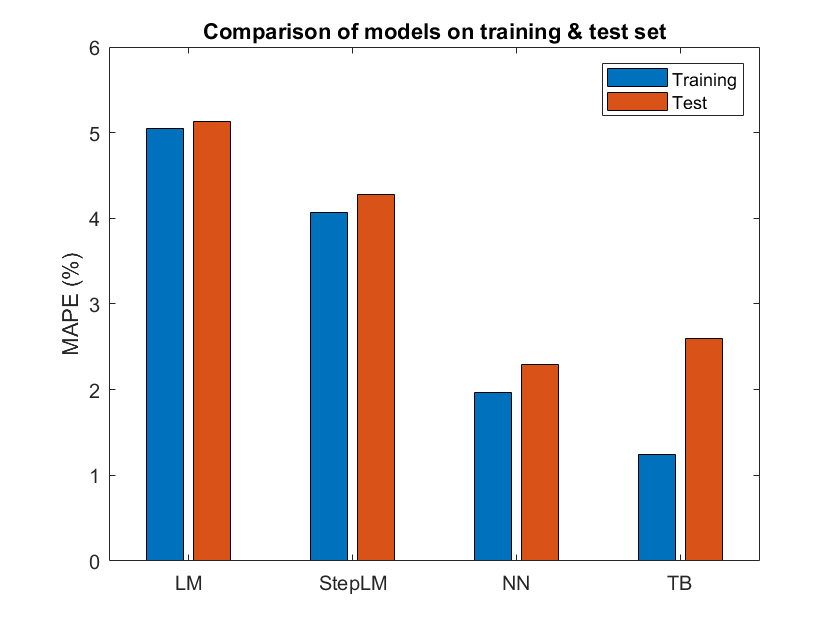

% make predictions on the test data set
Y_lm = predict(mdl_lm,modeltest);
Y_steplm = predict(mdl_steplm,modeltest);
Y_nn = mdl_net(Xtest')';
Y_tb = predict(mdl_tb,Xtest);
% concatenate predictions and mape for training and test sets
predTest = [Y_lm, Y_steplm, Y_nn, Y_tb];
predTrain = [Ytrain_lm, Ytrain_steplm, Ytrain_nn, Ytrain_tb];

perfTest = mape(Ytest, predTest);
perfTrain = mape(Ytrain, predTrain);
% plot the training and test mape for all three techniques
figure
bar([perfTrain;perfTest]'*100); 
xticklabels({'LM', 'StepLM', 'NN', 'TB'});
legend('Training','Test')
ylabel('MAPE (%)')
title('Comparison of models on training & test set')

## Further Validation

While our model may do well on average it could still be struggling in isolated cases, so let's look at exactly how it does on the test data. In the plot below the measured response is overlayed on top of the 24 hour ahead prediction.

If we zoom and pan in the plot, we can see that while the model is doing fairly well most of the time, there are some isolated cases where it struggles. A big one is around the end of October 2014. This was a result of the historic hurricane Sandy hitting the New York area, which caused widespread power outages and cancellations of school and work. Our model is not able to capture this, which should be expected. But what should we do with the data? This situation is such an extreme outlier, that it is probably best to remove it from the data set entirely. Doing so will lower our test error rate and give a more accurate account of how the model will do under non-hurricane conditions.

Other common areas where the model struggles are around the holidays. Holidays are big deviations from normal behavior, and our model currently has no way of knowing when they occur. We can capture this behavior by creating a new binary feature that contains if that time stamp was part of a holiday, yes or no. 

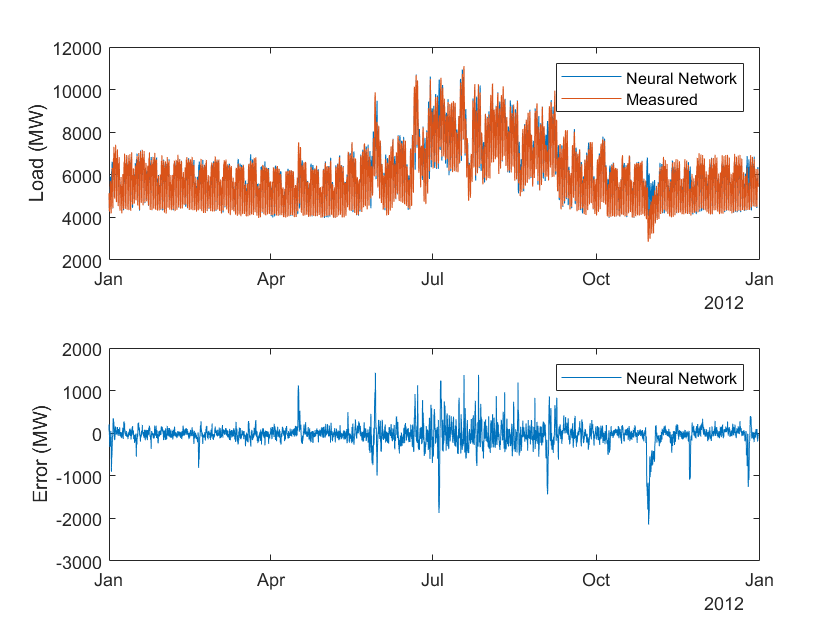

figure
t = tiledlayout(2, 1);
tt(1) = nexttile(t);
plot(modelData.Date(idxtest), Y_nn, 'DisplayName', 'Y_nn')
hold on
plot(modelData.Date(idxtest), Ytest, 'DisplayName', 'Ytest')
hold off
legend('Neural Network', 'Measured')
ylabel('Load (MW)')

tt(2) = nexttile(t);
plot(modelData.Date(idxtest), Ytest-Y_nn);
legend('Neural Network')
ylabel('Error (MW)')
linkaxes(tt, 'x')

*Copyright 2014-2020 The MathWorks, Inc.*